clear all;
clc;
global K;
%% 定义小车倒立摆物理性质
r = 0.075; %车轮的半径
d= 0.4048; %左轮、右轮两个轮子间的距离
l = 0.085; %摆杆质心到转轴距离
m = 0.32; %车轮的质量
M = 10.43; %摆杆质量
I = (1/2)*m*r^2; %车轮的转动惯量
Jz = (1/3)*m*l^2; %机器人机体对 z 轴的运动时产生的转动惯量(俯仰方向)
Jy = (1/12)*m*d^2; %机器人机体对 y 轴的运动时产生的转动惯量(偏航方向)
g = 9.8; %重力加速度b = 1e-4;
%% 状态空间矩阵
Q_eq = Jz*M + (Jz+M*l*l) * (2*m+(2*I)/r^2);
% A为系统矩阵
A_23=-(M^2*l^2*g)/Q_eq;
A_43=M*l*g*(M+2*m+(2*I/r^2))/Q_eq;
A = [0 1 0 0;
0 0 A_23 0;
0 0 0 1;
0 0 A_43 0]

A = 1.0e+03 *

         0    0.0010         0         0
         0         0   -0.0950         0
         0         0         0    0.0010
         0         0    1.2199         0


% B为输入矩阵
B_21=(Jz+M*l^2+M*l*r)/Q_eq/r;
B_41=-((M*l/r)+M+2*m+(2*I/r^2))/Q_eq;
B = [0 ;
2*B_21;
0 ;
2*B_41]

B =          0
   46.8830
         0
 -572.2525


% C为输出矩阵
C = [1 0 0 0;
0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0;0]

D =      0
     0


%% 求LQR增益矩阵
Q = diag([4 4 6 4]); % x dx q dq
R = 0.9;
S=diag([10 10 60 120]);
K = lqr(ss(A, B, C, D),Q,R)

K =    -2.1082   -3.5514  -11.7998   -2.4158


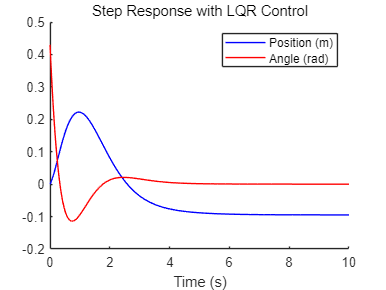

%% LQR闭环控制
% 初始条件
x0=[0 0 0.43 0];
% 设置时间范围
t = 0:0.01:10;
% 设置输入
u =0.2*ones(size(t));
Ac = (A-B*K);
Bc = B;
Cc = C;
Dc = D;
% Gd_1=[  0;
%     0.4779;
%    -0.0289;
%    -5.8396];
% Fd_1=[1.0000    0.0100   -0.0048   -0.0000;
%          0    1.0000   -0.9689   -0.0048;
%          0         0    1.0616    0.0102;
%          0         0   12.4485    1.0616];
% Ac=(Fd_1-Gd_1*K);
% BC=Gd_1;

% 生成状态空间模型
sys_close = ss(Ac,Bc,Cc,Dc);
% 对输入函数的响应
[y,t,x]=lsim(sys_close,u,t,x0);
% 绘图
figure;
hold on;
plot(t, y(:,1), 'b', 'LineWidth', 0.5); % 位移
plot(t, y(:,2), 'r', 'LineWidth', 0.5); % 倾角
hold off;
legend('Position (m)', 'Angle (rad)');
xlabel('Time (s)');
title('Step Response with LQR Control');